# SysMIC M1: Assignment 8

If you need help for this assignment please make use of the [session 8 forum](http://sysmic.ac.uk/moodle/mod/forum/view.php?id=2540).

When completed please save and upload here: [http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2453](http://sysmic.ac.uk/moodle/mod/assign/view.php?id=2453)  

After submission you can access model answers via the [session 8 review ](http://sysmic.ac.uk/moodle/mod/quiz/view.php?id=4143)activity.

`Name: [ Jade Lau ]`

## Exercise 3.4.1

([section link](https://sysmic.ac.uk/textbook/3.4-assignment---building-models.html#3.4))

Note that the model functions explored in the textbook `model_Epo1`, `model_Epo2` and a template for a further model `model_Epo3 `are included as local functions at the end of this Live Script.

**1. Original EpoR Model **

The original EpoR activation model is:


$$\textrm{EpoR}\overset{k_1 \times \;\textrm{Epo}}{\underset{k_2 }{\leftharpoondown^{\rightharpoonup } }} \textrm{pEpoR}$$
 

and the code to simulate this system is coded as local function `model_Epo1` at the end of this file.

Write code to run simulations using this model setting:

Epo=1, initial EpoR=1, initial pEpoR=0, `t_range=[0,10]` and

a) `k1=1, k2=1`

b) `k1=2, k2=1`

c) `k1=1, k2=2`

d) `k1=2, k2=2`

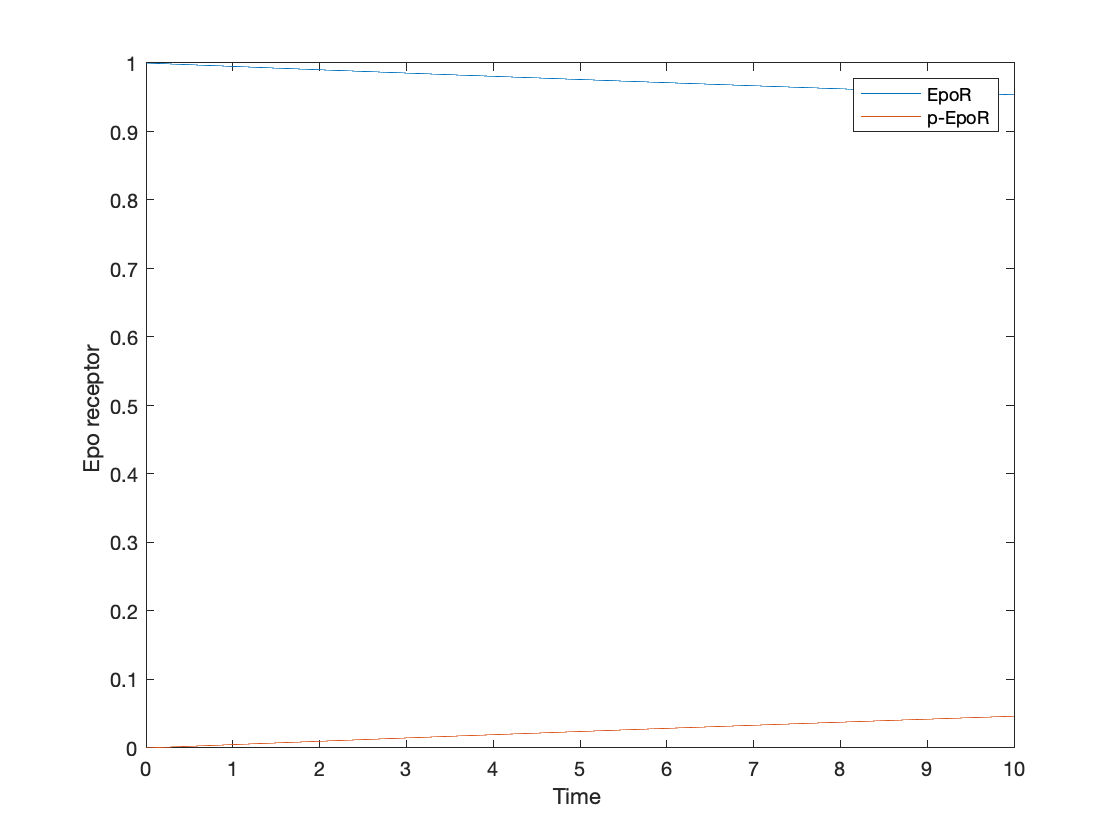

% answer
% Settings
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range= [0 10];
x_ini= [1 0];
Epo = 1; % Epo concentration

% a
% k1= 1;  %     Rate of EpoR phosphorylation
% k2= 1;  %     Rate of EpoR dephosphorylation

% b
% k1= 2;  %     Rate of EpoR phosphorylation
% k2= 1;  %     Rate of EpoR dephosphorylation

% c
% k1= 1;  %     Rate of EpoR phosphorylation
% k2= 2;  %     Rate of EpoR dephosphorylation

% d
% k1= 2;  %     Rate of EpoR phosphorylation
% k2= 2;  %     Rate of EpoR dephosphorylation

p = [k1 k2 Epo];
% Simulation
[t,x]=ode45(@model_Epo1,t_range,x_ini,options,p);
% Plot time series of all variables
figure(1);
plot(t,x(:,:));
xlabel('Time ');
ylabel('Epo receptor ');
 legend('EpoR', 'p-EpoR');

Use the results you find to describe how the values of `k1` and `k2` effect the behaviour of the model.

You will notice that none of these produce the overshoot phenomenon seen in experimental data.

***Comments:***

When the rate of phophorylation and dephosphorylation are equal the concentrations of both converge at 0.5 from their respective intial concentrations reaching an equilibrium. This occurs around 3 minutes. The speed at which convergence is met when the rates are same is governed by the magnitude of the rate, the higher the value the quicker the concentrations converge at 0.5.

When K1 is larger than K2, the concentration over time is similar to that of 3.2.1 where each species start off at their initial concentrations and fall/rise to 0.5 in about 30 seconds where they crossover. They continue to fall/rise until the 2 minute mark where both non-phosphorylated and phosphorylated concentrations level off at 0.65 and 0.35 respectively.

When K2 is larger than K1, the concentration of the non-phosphorylated receptor and the phosphorylated receptor fall or rise, respectively, for about 1 minute then maintains a steady concentration of just over 0.3 for phosphorylated and just under 0.7 for non-phosphorylated.

**2. Original EpoR Model **

In section 3.3 we made an extension that created the overshoot phenomenon by assuming the creation of a downstream molecule that activates the dephosphorylation of pEpoR (this is encoded in the local model function `model_Epo2` at the end of this file.)

Alternatively, it is also possible that downstream processes create a molecule which inhibits the phosphorylation of EpoR. We will now try to implement this alternative and study its impact on the receptor activation.

First we assume a process which leads to the creation of an inhibitor. This process should depend on the presence of the phosphorylated receptor pEpoR


$$\frac{\mathrm{d}\left\lbrack X\right\rbrack }{\textrm{dt}}=k_3 \times \left\lbrack \textrm{pEpoR}\right\rbrack$$


This equation describes the production of inhibitor when phosphorylated receptor is present.

Now we need to modify the equation of the production of the phosphorylated receptor pEpoR such that the rate decreases when the amount of inhibitor increases. In kinetics one way to describe the inhibition of a reaction $S\longrightarrow P$ is to use the following rate law:


$$\frac{\mathrm{d}\left\lbrack S\right\rbrack }{\textrm{dt}}=\frac{-k_0 \times \;\left\lbrack S\right\rbrack }{1+k_I \left\lbrack I\right\rbrack }$$


Here S is the substrate of the reaction which is consumed. $k_I$ is a parameter which controls the strength of the inhibition. In the absence of inhibitor ($\left\lbrack I\right\rbrack =0$) the rate is given by $-k_0 \times \;\left\lbrack S\right\rbrack$. In the presence of inhibitor ($\left\lbrack I\right\rbrack >0$), the rate will be lower than in its absence. This is because the concentration of the inhibitor appears in the denominator. Note how this is reminiscent of the way inhibition was formulated in the toggle switch.

Now we want to use this type of law in our receptor activation. After including this inhibition the set of model equations becomes:


$$\frac{ d[EpoR] }{dt} =    \frac{- k_1 \cdot [EpoR]\cdot[Epo]}{1+k_{4} \cdot [X]} + k_2 \cdot [p\mbox{-}EpoR]\\  
\frac{ d[p\mbox{-}EpoR] }{dt} = \frac{+ k_1 \cdot [EpoR]\cdot[Epo]}{1+k_{4} \cdot [X]} - k_2 \cdot [p\mbox{-}EpoR]\\  
\frac{ d[X] }{dt} = k_3 \cdot [p\mbox{-}EpoR]  \\  
$$


Complete the local function `model_Epo3`  template provided at the end of this file to model the above rate equations and below write the script to run a simulation using this modified model.

a) Initially put all parameters equal to 1 and run a simulation. Next vary the values of `k3` and `k4`. Describe how they change the behaviour of the system.

(Hint. Overlay plots for `k3=1`, `k4=1` then `k3=10`, `k4=1` and `k3=1`, `k4=10` then comment on what you find.)

% Settings
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range= [0 70];
x_ini= [1 0 0];

% Initial options for k1 = k2 = k3 = k4 = 1:
k1 = 1; % Rate of EpoR phosphorylation
k2 = 1; % Rate of p-EpoR dephosphorylation
k3= [1 10 1]; % Rate of X activation
k4= [1 1 10]; % Rate of inhibition

Epo = 1;

p = [k1 k2 k3 k4 Epo];
a = [k1 k2 k3(2) k4(2) Epo];
b = [k1 k2 k3(3) k4(3) Epo];
c = [1 1 1 30 1];

% % Simulation
[t,x]=ode45(@model_Epo3,t_range,x_ini,options,p);
% Plot time series of pEpoR
figure();
p1 = plot(t,x(:,2),'o');
hold on

% Simulation
[t,x]=ode45(@model_Epo3,t_range,x_ini,options,a);
% Plot time series of pEpoR
p2 = plot(t,x(:,2),'d');
hold on

% Simulation
[t,x]=ode45(@model_Epo3,t_range,x_ini,options,b);
% Plot time series of pEpoR
p3 = plot(t,x(:,2),'x');

% Simulation
[t,x]=ode45(@model_Epo3,t_range,x_ini,options,c);
% Plot time series of pEpoR
p4 = plot(t,x(:,2),'b');

hold on;
load('pEpoR_timeseries.mat');
errorbar(t_data,y_data,l_data,u_data,'o');
% hold on; % to overlay your model data

xlabel('time');
ylabel('Phosphorylated EpoR');
% ylim([-0.05,1.5]);
% xlim([-1,70]);
legend('k3=1, k4=1', 'k3=10, k4=1','k3=1, k4=10', 'Optimal');


b) You can load experimental data into MATLAB by downloading the data file `pEpoR_timeseries.mat` which contains time series data for p-EpoR  then running the following commands:

`>> load('pEpoR_timeseries.mat');`

`>> errorbar(t_data,y_data,l_data,u_data,'o');`

`>> hold on; % to overlay your model data`

Can you find values of `k1`, `k2`, `k3` and `k4` which match the experimental data? Comment on the approach you took, and how successful you were.

(Do not spend more than about 15 minutes on this. If you can't find a good fit, show your best attempt and describe why you found fitting the data difficult.)

% answer
 
c = [1 1 1 30 1];

% I adjusted k4 in a trial and error fashion. I think the match is close
% but not perfect. There is good fit for the first 2-3 minutes and from 20
% minutes onward.

***Comments:***

*Answer to a: When k3 and k4 are equal, and when k4 = 10 the concentration of the receptor over time is the same. However when k3, the rate of X activation is 10 and k4 is 1, the receptor concentrations is much lower peaking around 0.4.*

c) Model prediction: It is possible to run experiments where the downstream signalling cascade (initiated by the phosphorylated Epo receptor) is inhibited. In the current model this would mean that the production rate of inhibitor X is slowed.

Simulate this hypothetical experiment by reducing the rate constant of the reaction by which `pEpoR` activates X production by a factor of e.g. 10. How does the behaviour of the system change?

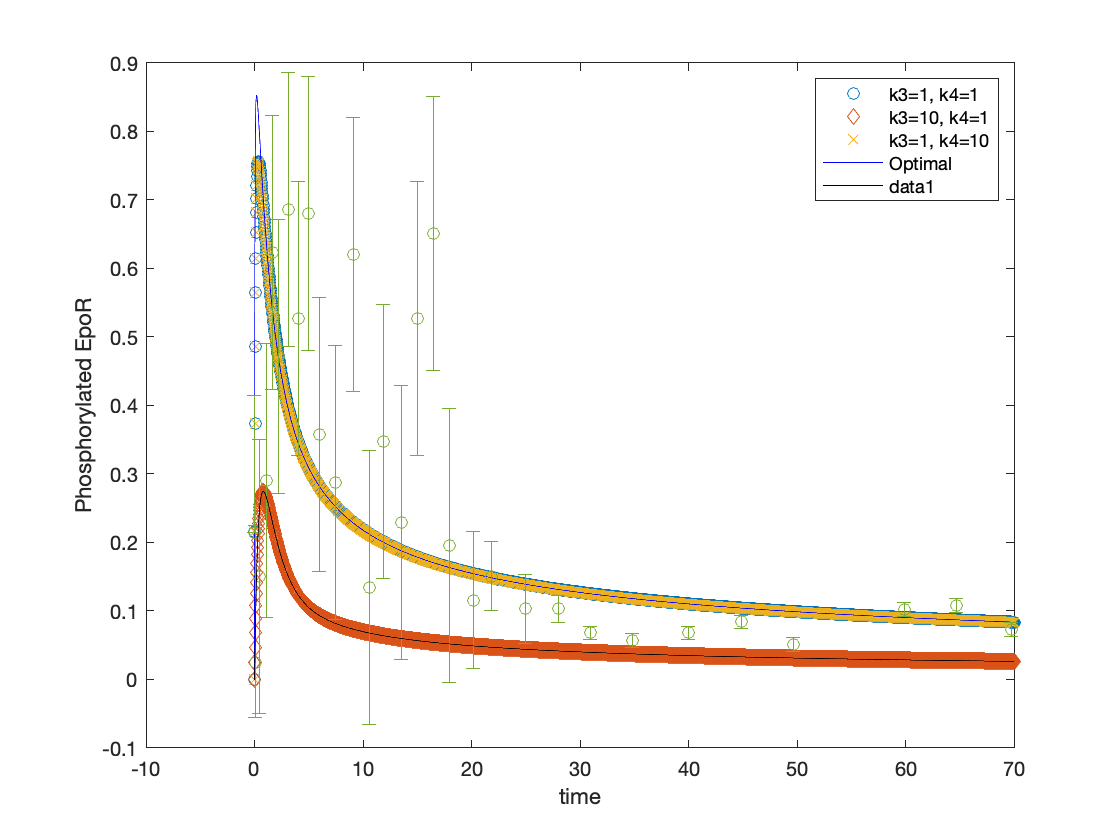

% answer
d = [1 1 10 1 1];

% Simulation
[t,x]=ode45(@model_Epo3,t_range,x_ini,options,d);
% Plot time series of pEpoR
p5 = plot(t,x(:,2),'black');

***Comments:***

**3. Comparison of extended EpoR Models**

Earlier in the textbook a modified model is suggested with two additional species:


$$
\frac{ d[EpoR] }{dt} =    - k_1 \cdot [EpoR]\cdot[Epo] + k_2 \cdot [p\mbox{-}EpoR] \cdot [Unknown2] \\  
\frac{ d[p\mbox{-}EpoR] }{dt} = k_1 \cdot [EpoR]\cdot[Epo] - k_2 \cdot [p\mbox{-}EpoR] \cdot [Unknown2]  \\  
\frac{ d[Unknown1] }{dt} = k_3 \cdot [p\mbox{-}EpoR] - k_4 \cdot [Unknown1]  \\  
\frac{ d[Unknown2] }{dt} = k_4 \cdot [Unknown1] - k_5 \cdot [Unknown2]  \\  
$$


The code to run this can be seen in the model answer from exercise [3.3.1](https://sysmic.ac.uk/textbook/3.3-improving-the-model.html#ex3.3.1) and as local function `model_Epo2` at the end of this file. 

Write code in the box below to run simulations of this model to investigate the alternative mechanism. Specifically, set `k5` to large and small values to test its impact.

% Settings
options = odeset('InitialStep',0.1,'MaxStep',0.1);
t_range= [0 70];
x_ini= [0.5 0 0 0];
k1= 0.005;  %     Rate of EpoR phosphorylation
k2 = 0.01;
k3 = 10;
k4 = 0.1;
% k5 = 0.01; % peaks around 0.4 and stabilises around 0.4 after 40 mins
% k5 = 1; % less overshoot - stabilises near the peak
Epo= 50;
p = [k1 k2 k3 k4 k5 Epo];

% Simulation
[t,x]=ode45(@model_Epo2,t_range,x_ini,options,p);
% Plot time series of pEpoR
figure();
p1 = plot(t,x(:,2));
l1 = 'k1=0.005 k2=0.01 k3=10 k4=0.1 k5=0.01'

l1 = 'k1=0.005 k2=0.01 k3=10 k4=0.1 k5=0.01'

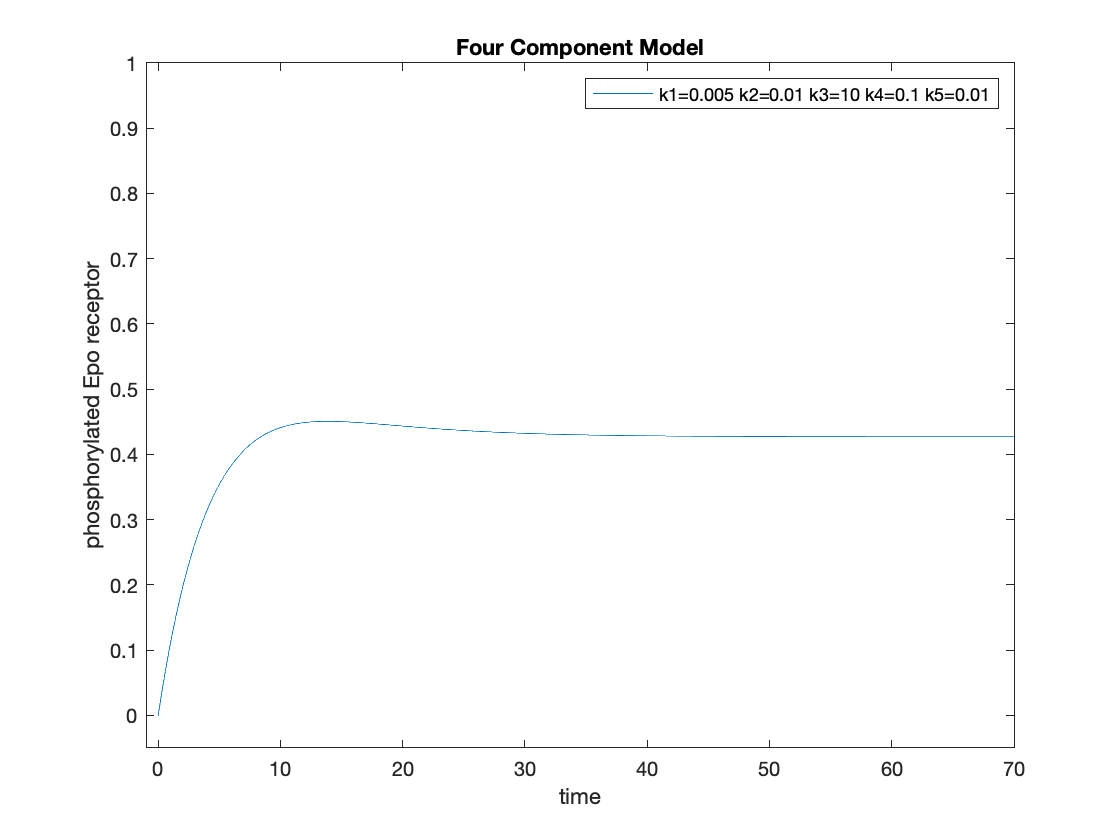

xlabel('time');
ylabel('phosphorylated Epo receptor');
ylim([-0.05,1]);
xlim([-1,70])
title('Four Component Model')
legend(p1, l1);

a) Describe similarities and differences of the behaviour of the two alternative extended models. How does the inclusion of molecular species with positive effect on the dephosphorylation affect the behaviour compared to the case where the concentration of X inhibits phosphorylation.

***Comments:***

*Both models capture the overshoot. Model 3 is a better fit for the experimental data compared to Model 2. Adjusting the rates in Model 3 maintains the general shape of the experimental data however changing the rate of activation in Model 2 creates a poor fit.*

b) Based on your simulations, try to describe which model better fits the (limited) experimental data?

***Comments:***

***Model 3***

***Local functions:***

*(these are always placed together in single section at the end of the Live Script file) *

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 1 Original EpoR Model 


function dxdt=model_Epo1(t,x,p)
% Initialize model vector with zeroes,
dxdt=zeros(2,1);
% Parameters
k1=p(1);  %     Rate of EpoR phosphorylation
k2=p(2);  %     Rate of EpoR dephosphorylation
Epo=p(3);   %     Epo concentration

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Differential Equation:
%
% unphosphorylated EpoR
dxdt(1)= - k1*x(1)*Epo + k2*x(2);
% phosphorylated EpoR
dxdt(2)=   k1*x(1)*Epo - k2*x(2);
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%
function dxdt = model_Epo2(t,x,p)
 
% Initialize model vector with zeroes
dxdt = zeros(4,1);
    
% Parameters
k1 = p(1);
k2 = p(2);
k3 = p(3);
k4 = p(4);
k5 = p(5);
Epo= p(6);
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Differential Equations
%
% unphosphorylated EpoR
dxdt(1)=-k1*x(1)*Epo+k2*x(2)*x(4);
% phosphorylated EpoR
dxdt(2)=k1*x(1)*Epo-k2*x(2)*x(4);
% Unknown 1
dxdt(3)=k3*x(2)-k4*x(3);
% Unknown 2
dxdt(4)=k4*x(3)-k5*x(4);
%%%%%%%%%%%%%%%%%%%%%%%%%%%
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%
function dxdt=model_Epo3(t,x,p)
% Initialize model vector with zeroes,
dxdt=zeros(3,1);

% Parameters
k1 = p(1);
k2 = p(2);
k3 = p(3);
k4 = p(4);
Epo = p(4);

% COMPLETE CODE BELOW
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Differential Equations
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% unphosphorylated EpoR
dxdt(1)=(-k1*x(1)*Epo)/(1+k4*x(3))+(k2*x(2));
% phosphorylated EpoR
dxdt(2)=(k1*x(1)*Epo)/(1+k4*x(3))-(k2*x(2));
% X
dxdt(3)=k3*x(2);



%%%%%%%%%%%%%%%%%%%%%%%%%%%
end